k=1

k = 1

x = 0:0.01:1

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


f = @(x) atan( k * sin(2*pi*x) ./ (1 + k*cos(2*pi*x)))

f = 値をもつ function_handle :
    @(x)atan(k*sin(2*pi*x)./(1+k*cos(2*pi*x)))


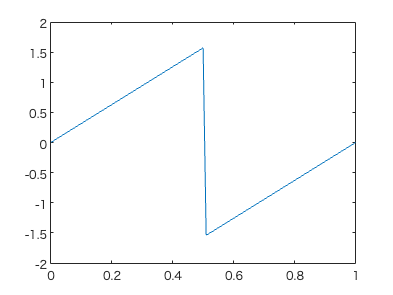

plot(x, f(x))

V = @(x) arrayfun(@(x) integral(f, 0, x), x)

V = 値をもつ function_handle :
    @(x)arrayfun(@(x)integral(f,0,x),x)


V(x)

ans =          0    0.0002    0.0006    0.0014    0.0025    0.0039    0.0057    0.0077    0.0101    0.0127    0.0157    0.0190    0.0226    0.0265    0.0308    0.0353    0.0402    0.0454    0.0509    0.0567    0.0628    0.0693    0.0760    0.0831    0.0905    0.0982    0.1062    0.1145    0.1232    0.1321    0.1414    0.1510    0.1608    0.1711    0.1816    0.1924    0.2036    0.2150    0.2268    0.2389    0.2513    0.2641    0.2771    0.2904    0.3041    0.3181    0.3324    0.3470    0.3619    0.3771


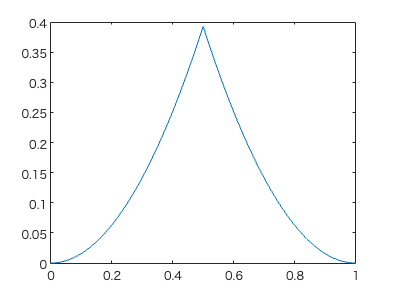

plot(x, V(x))